## Bridge of Doom

#### Grant Miner and Han Vakil

## 21.1

1.

% Creates a symbolic variable, u, used to find the symbolic equations for
% various quantities later in the script
syms u

% Establishes the distance between the two wheels
d = 0.235; %meters

% Represents the full parametric equation
r = @(u) 4*(0.3960*cos(2.65*(u + 1.4))*[1 0] - 0.99*sin(u+1.4)*[0 1]);

% Creates an array of times to find the theoretical path. Only used for plotting.
times = linspace(0, 16, 200);

% Creates the direction-specific vectors for the parametric position function
rx = @(u) 4*(0.3960*cos(2.65*(0.2*u+1.4)));
ry = @(u) 4*(-0.99*sin(0.2*u+1.4));

% Puts the position functions into an array function that represents the
% position vector.
position = @(u) [rx ry 0]

position = function_handle with value:
    @(u)[rx,ry,0]



% Assumes that u will be a positive value, helps with simplification.
assume(u, {'real', 'positive'})

% Finds the derivative of the position
rPrimeX = simplify(diff(rx, u));
rPrimeY = simplify(diff(ry, u));
rPrime = [rPrimeX rPrimeY 0];

% Determines the linear speed of the Neato over time
magRPrime = simplify(norm(rPrime))

$$magRPrime = \frac{99\,\sqrt{2500\,{\cos\left(\frac{u}{5}+\frac{7}{5}\right)}^{2}+2809\,{\sin\left(\frac{53\,u}{100}+\frac{371}{100}\right)}^{2}}}{6250}$$


% Symbolically calculates the unit tangent vector
T_hat = simplify(rPrime./norm(rPrime))

$$T\_hat = \begin{array}{l} \left(\begin{array}{ccc} -\frac{53\,\sin\left(\frac{53\,u}{100}+\frac{371}{100}\right)}{\sigma_{1}} & -\frac{50\,\cos\left(\frac{u}{5}+\frac{7}{5}\right)}{\sigma_{1}} & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sqrt{2500\,{\cos\left(\frac{u}{5}+\frac{7}{5}\right)}^{2}+2809\,{\sin\left(\frac{53\,u}{100}+\frac{371}{100}\right)}^{2}} \end{array}$$


% Finds the derivative of the unit tangent vector
dT_hat = simplify(diff(T_hat, u))

$$dT\_hat = \begin{array}{l} \left(\begin{array}{ccc} -\frac{\sqrt{2}\,\left(96725\,\cos\left(\frac{13\,u}{100}+\frac{91}{100}\right)+140450\,\cos\left(\frac{53\,u}{100}+\frac{371}{100}\right)+43725\,\cos\left(\frac{93\,u}{100}+\frac{651}{100}\right)\right)}{2\,\sigma_{1}} & \frac{\sqrt{2}\,\left(112360\,\sin\left(\frac{u}{5}+\frac{7}{5}\right)+205057\,\sin\left(\frac{43\,u}{50}+\frac{301}{50}\right)+92697\,\sin\left(\frac{63\,u}{50}+\frac{441}{50}\right)\right)}{4\,\sigma_{1}} & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\left(2500\,\cos\left(\frac{2\,u}{5}+\frac{14}{5}\right)-2809\,\cos\left(\frac{53\,u}{50}+\frac{371}{50}\right)+5309\right)}^{3/2} \end{array}$$


% Calculates the angular velocity as a function of time
omega = simplify(cross(T_hat, dT_hat))

$$omega = \left(\begin{array}{ccc} 0 & 0 & -\frac{9672500\,\cos\left(\frac{7\,u}{100}+\frac{49}{100}\right)+40540601\,\cos\left(\frac{33\,u}{100}+\frac{231}{100}\right)+17375361\,\cos\left(\frac{73\,u}{100}+\frac{511}{100}\right)+4372500\,\cos\left(\frac{113\,u}{100}+\frac{791}{100}\right)-10868021\,\cos\left(\frac{139\,u}{100}+\frac{973}{100}\right)-4912941\,\cos\left(\frac{179\,u}{100}+\frac{1253}{100}\right)}{4\,{\left(2500\,\cos\left(\frac{2\,u}{5}+\frac{14}{5}\right)-2809\,\cos\left(\frac{53\,u}{50}+\frac{371}{50}\right)+5309\right)}^{2}} \end{array}\right)$$


% Finds the magnitude of the angular velocity, while also preserving the
% direction of the vector
magOmega = simplify(dot(omega, [0 0 1]))

$$magOmega = -\frac{9672500\,\cos\left(\frac{7\,u}{100}+\frac{49}{100}\right)+40540601\,\cos\left(\frac{33\,u}{100}+\frac{231}{100}\right)+17375361\,\cos\left(\frac{73\,u}{100}+\frac{511}{100}\right)+4372500\,\cos\left(\frac{113\,u}{100}+\frac{791}{100}\right)-10868021\,\cos\left(\frac{139\,u}{100}+\frac{973}{100}\right)-4912941\,\cos\left(\frac{179\,u}{100}+\frac{1253}{100}\right)}{4\,{\left(2500\,\cos\left(\frac{2\,u}{5}+\frac{14}{5}\right)-2809\,\cos\left(\frac{53\,u}{50}+\frac{371}{50}\right)+5309\right)}^{2}}$$


% Calculates the speed of each wheel over time
V_L = simplify(magRPrime - magOmega*(d/2))

$$V\_L = \frac{47\,\left(9672500\,\cos\left(\frac{7\,u}{100}+\frac{49}{100}\right)+40540601\,\cos\left(\frac{33\,u}{100}+\frac{231}{100}\right)+17375361\,\cos\left(\frac{73\,u}{100}+\frac{511}{100}\right)+4372500\,\cos\left(\frac{113\,u}{100}+\frac{791}{100}\right)-10868021\,\cos\left(\frac{139\,u}{100}+\frac{973}{100}\right)-4912941\,\cos\left(\frac{179\,u}{100}+\frac{1253}{100}\right)\right)}{1600\,{\left(2500\,\cos\left(\frac{2\,u}{5}+\frac{14}{5}\right)-2809\,\cos\left(\frac{53\,u}{50}+\frac{371}{50}\right)+5309\right)}^{2}}+\frac{99\,\sqrt{2500\,{\cos\left(\frac{u}{5}+\frac{7}{5}\right)}^{2}+2809\,{\sin\left(\frac{53\,u}{100}+\frac{371}{100}\right)}^{2}}}{6250}$$

V_R = simplify(magRPrime + magOmega*(d/2))

$$V\_R = \frac{99\,\sqrt{2500\,{\cos\left(\frac{u}{5}+\frac{7}{5}\right)}^{2}+2809\,{\sin\left(\frac{53\,u}{100}+\frac{371}{100}\right)}^{2}}}{6250}-\frac{47\,\left(9672500\,\cos\left(\frac{7\,u}{100}+\frac{49}{100}\right)+40540601\,\cos\left(\frac{33\,u}{100}+\frac{231}{100}\right)+17375361\,\cos\left(\frac{73\,u}{100}+\frac{511}{100}\right)+4372500\,\cos\left(\frac{113\,u}{100}+\frac{791}{100}\right)-10868021\,\cos\left(\frac{139\,u}{100}+\frac{973}{100}\right)-4912941\,\cos\left(\frac{179\,u}{100}+\frac{1253}{100}\right)\right)}{1600\,{\left(2500\,\cos\left(\frac{2\,u}{5}+\frac{14}{5}\right)-2809\,\cos\left(\frac{53\,u}{50}+\frac{371}{50}\right)+5309\right)}^{2}}$$


% Determines the function for the normal vector
N_hat = simplify(dT_hat./norm(dT_hat))

$$N\_hat = \begin{array}{l} \left(\begin{array}{ccc} -\frac{2\,\left(96725\,\sigma_{6}+140450\,\sigma_{5}+43725\,\sigma_{4}\right)}{\sigma_{1}} & \frac{112360\,\sin\left(\frac{u}{5}+\frac{7}{5}\right)+205057\,\sigma_{3}+92697\,\sigma_{2}}{\sigma_{1}} & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=53\,\sqrt{2500\,{\left(73\,\sigma_{6}+106\,\sigma_{5}+33\,\sigma_{4}\right)}^{2}+2809\,{\left(40\,\sin\left(\frac{u}{5}+\frac{7}{5}\right)+73\,\sigma_{3}+33\,\sigma_{2}\right)}^{2}}\\ \sigma_{2}=\sin\left(\frac{63\,u}{50}+\frac{441}{50}\right)\\ \sigma_{3}=\sin\left(\frac{43\,u}{50}+\frac{301}{50}\right)\\ \sigma_{4}=\cos\left(\frac{93\,u}{100}+\frac{651}{100}\right)\\ \sigma_{5}=\cos\left(\frac{53\,u}{100}+\frac{371}{100}\right)\\ \sigma_{6}=\cos\left(\frac{13\,u}{100}+\frac{91}{100}\right) \end{array}$$

% Creates a vector of times at which to plot the tangent and normal
% vectors on the parametric bridge plot
vector_times = [times(1) times(41) times(81) times(121) times(161) times(200)];

% Plots the position function
plot(rx(times), ry(times))
hold on
xlabel("Position (m)")
ylabel("Position (m)")
title("Bridge of Doom Path")

for n = 1:length(vector_times)
    % Sets the time at which to calculate the various vectors
    t = vector_times(n);
    
    % Finds the point where the Neato is at the given time
    X = rx(t);
    Y = ry(t);
    
    % Converts the symbolic equations into numeric form and calculates the
    % vectors at the given time
    T = double(subs(T_hat, u, t));
    N = double(subs(N_hat, u, t));
    
    % Draws the unit Tangent vector
    quiver(X,Y,T(1),T(2),'g')
    
    % Draws the unit Normal vector
    quiver(X,Y,N(1),N(2),'r')
end

% Equalizes the axes for an accurate representation of the path
axis("equal")

legend(["Bridge of Doom", "Tangent Vector", "Normal Vector"], "Location", "east")

hold off

## 21.2

% Converts the symbolic equations for speed and angular velocity into
% calculable functions of t
linearSpeed = @(t) double(subs(magRPrime, u, t));
angularVelocity = @(t) double(subs(omega(3), u, t));

% Loads the encoder data and extracts the data from the file
data = readmatrix("neato_take_2.csv");
posL = data(:,2);
posR = data(:,3);
timez = data(:,1);

% Calculates the velocity of each  wheel
dTimes = (timez(2:end) - timez(1:length(timez) - 1));
timesV = dTimes + timez(1:length(timez) - 1);
velL = (posL(2:end) - posL(1:length(posL) - 1)) ./ dTimes;
velR = (posR(2:end) - posR(1:length(posR) - 1)) ./ dTimes;

% Smooths the velocity data by taking a 3-point rolling average
smoothedVelL = (velL(1:length(velL) - 2) + velL(2:length(velL) - 1) + velL(3:end)) / 3;
smoothedVelR = (velR(1:length(velR) - 2) + velL(2:length(velR) - 1) + velR(3:end)) / 3;
smoothTime = timesV(2:length(timesV) - 1);
dSmoothTime = dTimes;

% Calculates the (smoothened via rolling average) angular and linear
% velocities.
smoothOmega = (smoothedVelR - smoothedVelL) / 2;
smoothV = (smoothedVelR + smoothedVelL) / 2;

% Slices out the useful section of the encoder data for linear and angular
% velocity, time, and left and right wheel velocity
V_dists_exp = smoothV(62:222);
dTimesDists_exp = dTimes(62:222);
velTimeStart = 61;
velTimeEnd = 221;
smoothTimePlot = smoothTime(velTimeStart:velTimeEnd) - 1575.7;
smoothedVelLPlot = smoothedVelL(velTimeStart:velTimeEnd);
smoothedVelRPlot = smoothedVelR(velTimeStart:velTimeEnd);

% NOTE: This section is for theoretical and experimental motion.

% Determines the starting direction of the Neato
startDir = (double(subs(T_hat, u, 0)));

% Creates an array that includes the direction the Neato faces (angle in radians) 
% over the whole path, where 0 is the global positive x-direction
% Theoretical:
heading_theory = cumtrapz(times, angularVelocity(times)) + asin(startDir(2));
% Experimental:
heading_exp = cumtrapz(timesV(2:length(timesV)-1), smoothOmega) * 12.7144 + asin(startDir(2));
heading_exp = heading_exp(61:221);

% Converts the direction the Neato faces into a matrix of vectors with x-
% and y-components
% Theoretical
dirs_theory = [cos(heading_theory)', sin(heading_theory)'];
% Experimental
dirs_exp = [cos(heading_exp), sin(heading_exp)];


% Calculates the total distance traveled between each interval and
% multiplies those values by the time step and the vectorized heading at
% each point. This creates an array of vectors that when added represent the
% encoder-collected path of the Neato.
% Theoretical
dists_theory = [linearSpeed(times)', linearSpeed(times)'] .* dirs_theory .* 16/200;
% Experimental
dists_exp = [V_dists_exp, V_dists_exp] .* dirs_exp .* dTimesDists_exp;


% Initializes an empty array to put the vectorized positions into
% Theoretical
poss_theory = zeros(size(dists_theory));
% Experimental
poss_exp = zeros(size(dists_exp));

% Establishes the Neato's starting position
% Theoretical
poss_theory(1,:) = [4*(0.3960*cos(2.65*(0.2*0+1.4))), 4*(-0.99*sin(0.2*0+1.4))];
% Experimental
poss_exp(1,:) = [4*(0.3960*cos(2.65*(0.2*0+1.4))), 4*(-0.99*sin(0.2*0+1.4))];

% Performs an Euler's Method-derived summation of vectors to determine the
% path of the Neato from the encoder data
%Theoretical
for i = 1:length(poss_theory) - 1
    poss_theory(i + 1,:) = poss_theory(i,:) + dists_theory(i,:);
end
%Experimental
for i = 1:length(poss_exp) - 1
    poss_exp(i + 1,:) = poss_exp(i,:) + dists_exp(i,:);
end


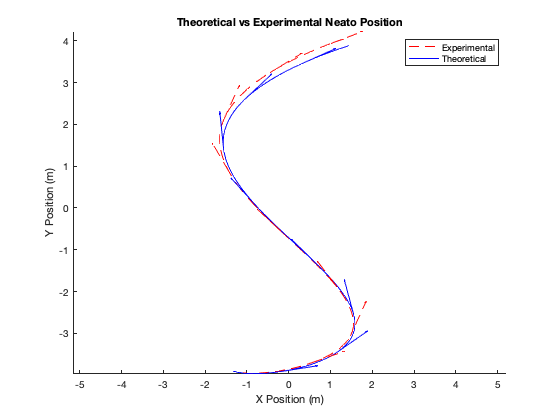

% Clears figure to prevent superimposed plots
clf
hold on
title("Theoretical vs Experimental Neato Position")
% Plots the positions of the Neato derived from the experimental encoder data
plot(poss_exp(:,1), poss_exp(:,2), "r--")

% Plots the positions of the Neato derived from the theoretical encoder data
plot(poss_theory(:,1),poss_theory(:,2), "b-")

% Defines the number of tangent vectors to be drawn
num_tangents = 8;


for n = 1:num_tangents
    % Chooses which point the tangent vector will be drawn at. Experimental
    % is offset to prevent near-overlap between tangent vectors
    theory_pos = floor(n * length(poss_theory) / (num_tangents + 1));
    exp_pos = floor((n + 0.5) * length(poss_exp) / (num_tangents + 1));
    
    % Determines the starting coordinate for the tangent vectors, equal to 
    % the position coordinates of the Neato 
    theoryCoords = poss_theory(theory_pos,:);
    expCoords = poss_exp(exp_pos,:);
    
    % Determines the direction of the tangent vectors, easily pulled from
    % the previously calculated direction the robot is heading
    theoryDir = dirs_theory(theory_pos, :);
    expDir = dirs_exp(exp_pos, :);
    
    % Plots the tangent vectors for both the theoretical and experimental
    % encoder position data
    quiver(theoryCoords(1), theoryCoords(2), theoryDir(1), theoryDir(2), "b-");
    quiver(expCoords(1), expCoords(2), expDir(1), expDir(2), "r--");
    
end
legend('Experimental','Theoretical')

% Sets the axes to equal to ensure perception of the figure isn't muddled
% by differently-scaled axes
axis equal
xlabel("X Position (m)")
ylabel("Y Position (m)")

hold off

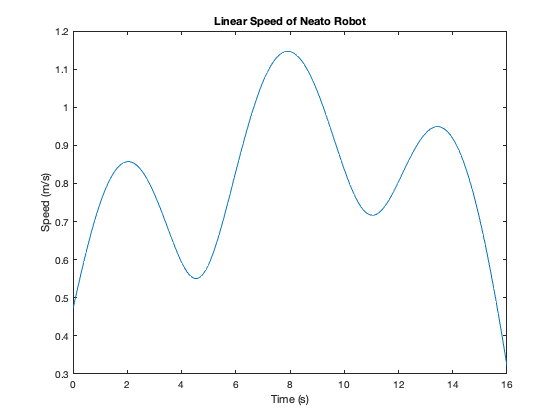

clf
plot(times, linearSpeed(times))
hold on
xlabel("Time (s)")
ylabel("Speed (m/s)")
title("Linear Speed of Neato Robot")
hold off

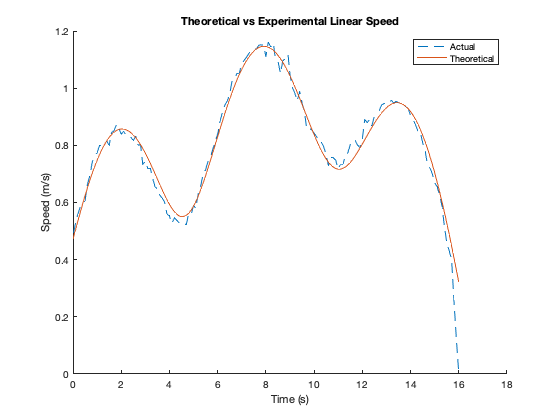

clf
hold on
title('Theoretical vs Experimental Linear Speed')
plot(timesV(61:221)' - 1575.7, V_dists_exp, '--')
plot(times,linearSpeed(times))
legend('Actual', 'Theoretical')
xlabel("Time (s)")
ylabel("Speed (m/s)")
hold off

plot(times, angularVelocity(times))
hold on
xlabel("Time (s)")
ylabel("Angular Velocity (rad/s)")
title("Angular Velocity of Neato Robot")
hold off

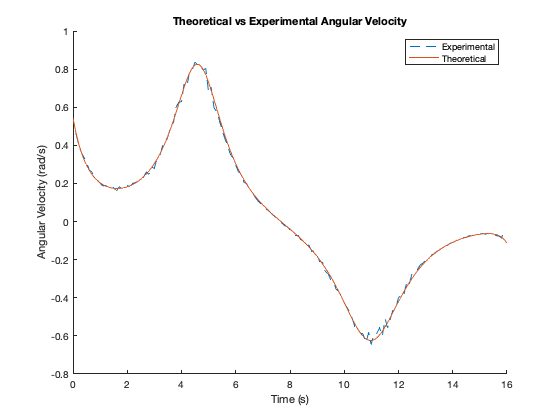

clf
hold on
title('Theoretical vs Experimental Angular Velocity')
plot(timesV(62:220) - 1575.7, smoothOmega(62:220) * 12.7144, "--")
plot(times, angularVelocity(times))
legend('Experimental', 'Theoretical')
xlabel("Time (s)")
ylabel("Angular Velocity (rad/s)")
hold off

## 21.3

leftVelocity = @(t) double(subs(V_L, u, t));
rightVelocity = @(t) double(subs(V_R, u, t));

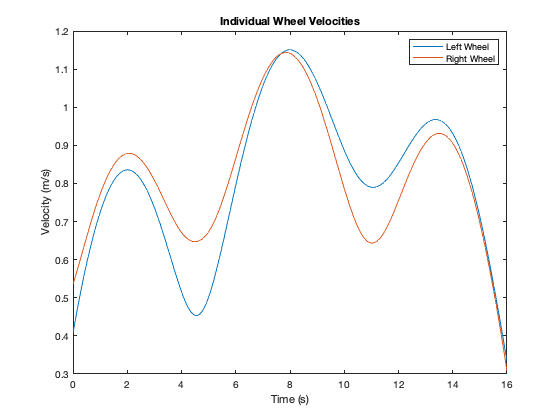

plot(times, leftVelocity(times), times, rightVelocity(times))
hold on
xlabel("Time (s)")
ylabel("Velocity (m/s)")
title("Individual Wheel Velocities")
legend(["Left Wheel", "Right Wheel"])
hold off

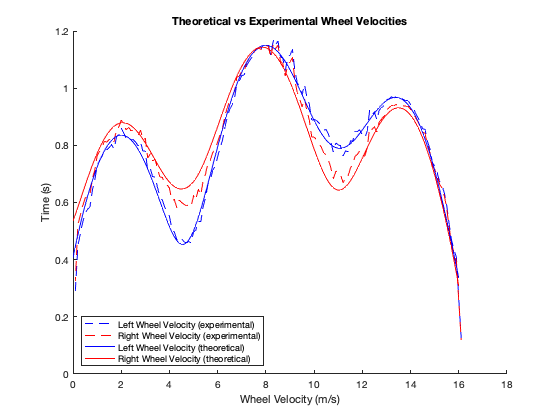

clf
hold on
title('Theoretical vs Experimental Wheel Velocities')
plot(smoothTimePlot, smoothedVelLPlot, "b--")
plot(smoothTimePlot, smoothedVelRPlot, "r--")
plot(times, leftVelocity(times), "b")
plot(times, rightVelocity(times), "r")
legend("Left Wheel Velocity (experimental)", "Right Wheel Velocity (experimental)", ...
    "Left Wheel Velocity (theoretical)", "Right Wheel Velocity (theoretical)", ...
    "Location", "southwest")
xlabel("Wheel Velocity (m/s)")
ylabel("Time (s)")
hold off